## M2P1 Memo

### Exercise 1

A perfect code like the one below is 10 points. 

- Vector: 2

- Rotation matrix: 5 

- Figures: 3

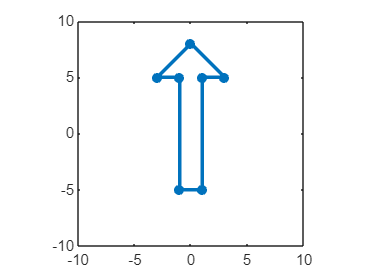

V = [ -1  -1  -3   0   3   1   1  
      -5   5   5   8   5   5  -5  ];
figure(1)
dot2dot(V)

theta = -pi+pi/6

theta = -2.6180

G = [cos(theta) -sin(theta); sin(theta) cos(theta)]

G =    -0.8660    0.5000
   -0.5000   -0.8660


W=G*V

W =    -1.6340    3.3660    5.0981    4.0000   -0.0981    1.6340   -3.3660
    4.8301   -3.8301   -2.8301   -6.9282   -5.8301   -4.8301    3.8301


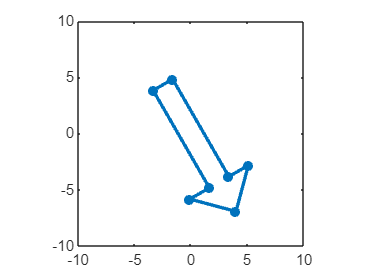

figure(2)
dot2dot(W)

### Exercise 2 [20] 

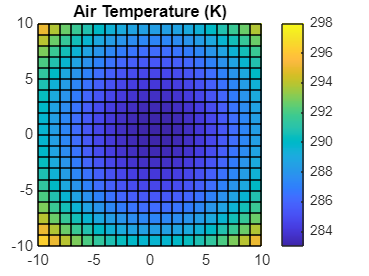

% 5 points 
x=-10:10;
y=-10:10;
[X,Y]=meshgrid(x,y);

% 5 points
T=283+(X.^2+Y.^2)/15;
figure
pcolor(X,Y,T)
colorbar
clim([283,298]) % I want a nice range! -2 if not done
title('Air Temperature (K)')

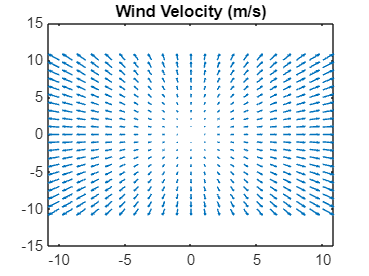


% 10 points
F1=2*X;
F2=2*Y;
figure
quiver(X,Y,F1,F2)
title('Wind Velocity (m/s)')

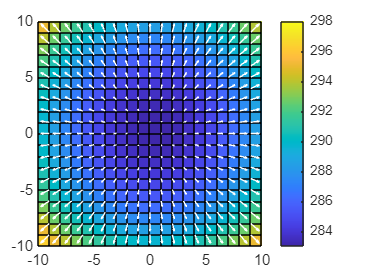



% Bonus figure [10 points]
% all together now (this is difficult, since they need to use clim)
% 
figure
pcolor(X,Y,T)
clim([283,298])
colorbar
hold on
quiver(X,Y,F1,F2,'w')